This script is to analyze the autofluorescence in FLP experiments.

The data is collected on 21st Dec 2021, from mouse PM13_noEP and KQ17.

Each mouse was recorded for 10 minutes, with maximum laser power (voltage=4, ND filter adjusted to maximum).

cd('/Users/pingchuanma/Desktop/ChenLab_Data/some raw data/122121_autofluorescence_001')
PM13file='continuous aquistion data_7';
KQ17file='continuous aquistion data_14';
timebin=1;
ch=1;

load(PM13file)



% first load FLIM file 007 to do the fitting.

load(PM13file);
filename='PM13_autofluo.mat';
load(filename)
autofluorescence_FLP=mean(lifetime_histograms');


FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);
load(filename)

time(isnan(time))=[];
photoncount(isnan(photoncount))=[];
tau_avg(isnan(tau_avg))=[];
tau_avgTrunc(isnan(tau_avgTrunc))=[];
tau_empTrunc(isnan(tau_empTrunc))=[];
p1(isnan(p1))=[];
chi2(isnan(chi2))=[];

save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2');

PM13_tau_empTrunc=tau_empTrunc;
PM13_photoncount=photoncount;
PM13_tau_avg=tau_avg;
PM13_time=time;


% first load FLIM file 014 to do the fitting.

load(KQ17file);
filename='KQ17_autofluo.mat';

FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);
load(filename)

time(isnan(time))=[];
photoncount(isnan(photoncount))=[];
tau_avg(isnan(tau_avg))=[];
tau_avgTrunc(isnan(tau_avgTrunc))=[];
tau_empTrunc(isnan(tau_empTrunc))=[];
p1(isnan(p1))=[];
chi2(isnan(chi2))=[];

save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2');

KQ17_tau_empTrunc=tau_empTrunc;
KQ17_photoncount=photoncount;
KQ17_tau_avg=tau_avg;
KQ17_time=time;



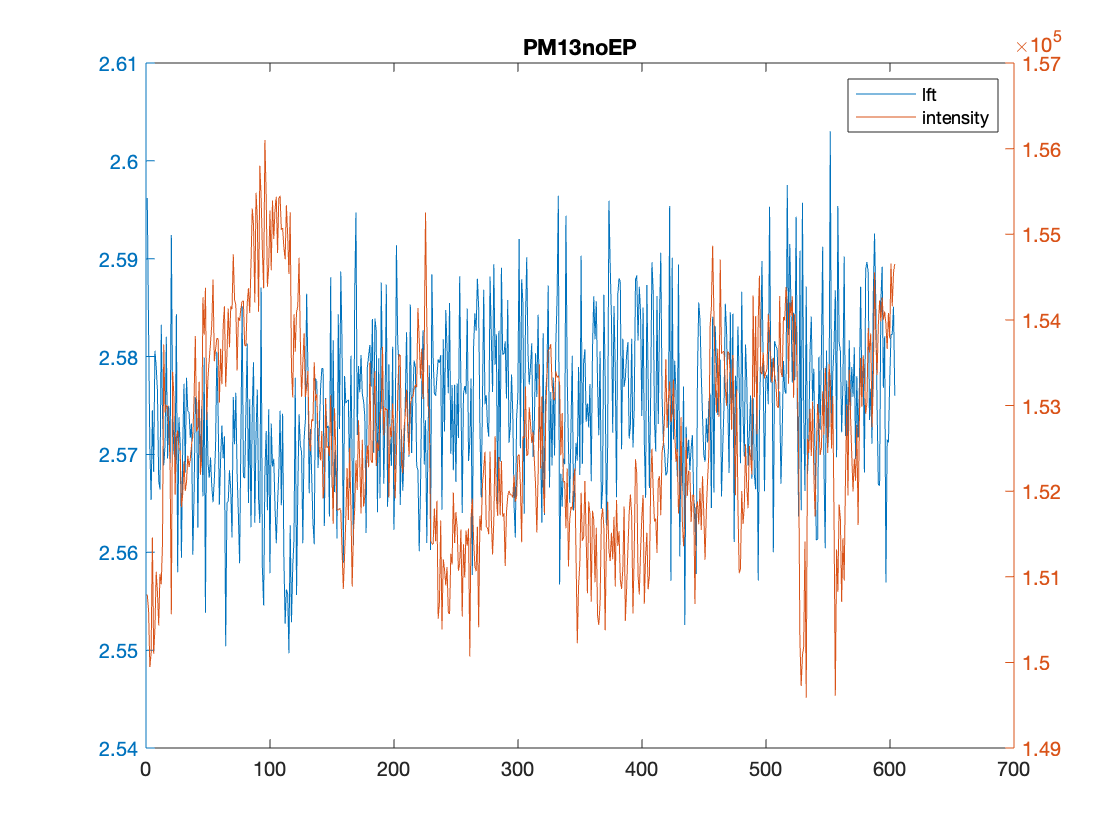

figure
yyaxis left
plot(PM13_time, PM13_tau_empTrunc)
yyaxis right
plot(PM13_time, PM13_photoncount)
title('PM13noEP')
legend('lft','intensity')

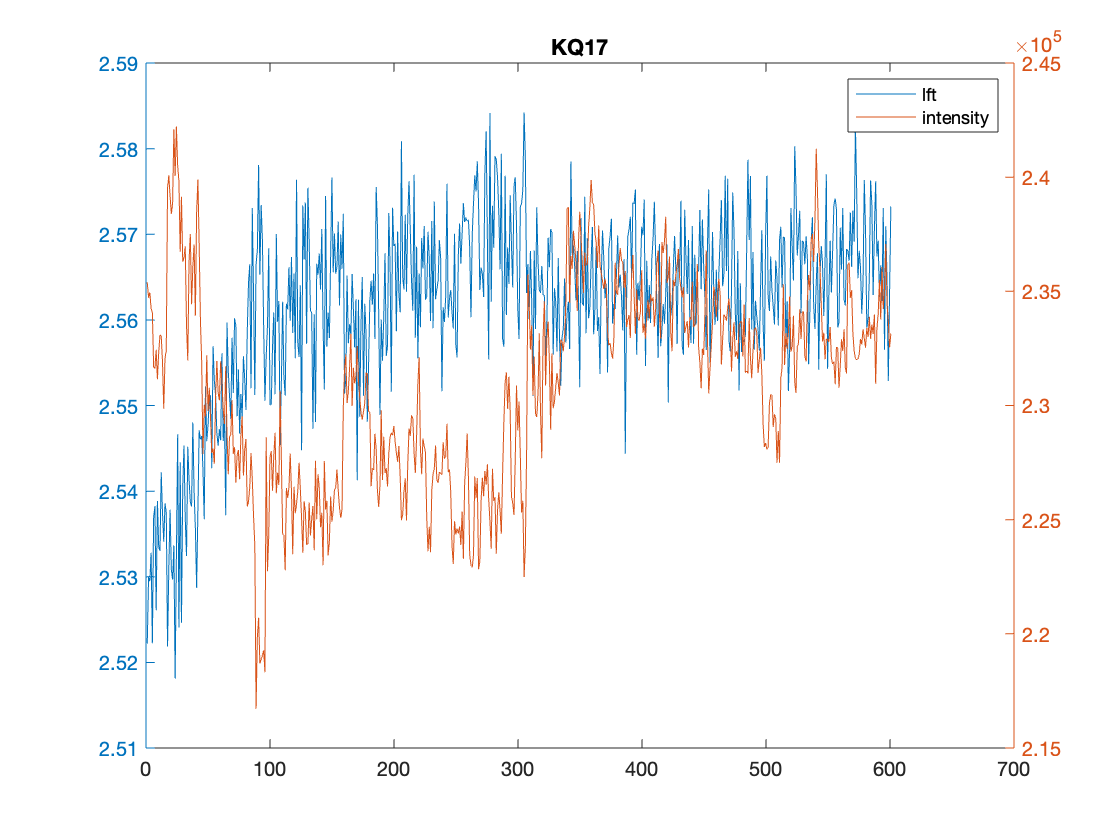


figure
yyaxis left
plot(KQ17_time, KQ17_tau_empTrunc)
yyaxis right
plot(KQ17_time, KQ17_photoncount)
title('KQ17')
legend('lft','intensity')